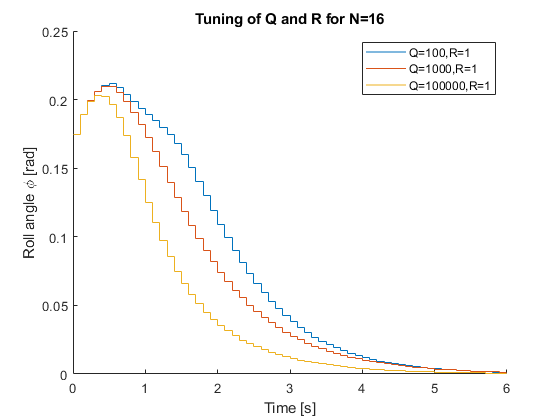

clear all
close all

xlim = 60;
t = linspace(0,6,60+1);

load('MPC_reg_states_N_16\States_N_16_v_2_Q_0_1_R_1.mat')
x_Q_0_1_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_1_R_1.mat')
x_Q_1_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_10_R_1.mat')
x_Q_10_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_100_R_1.mat')
x_Q_100_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_1000_R_1.mat')
x_Q_1000_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_10000_R_1.mat')
x_Q_10000_R_1 = x;

load('MPC_reg_states_N_16\States_N_16_v_2_Q_100000_R_1.mat')
x_Q_100000_R_1 = x;

figure(1)
hold on
% stairs(t,x_Q_0_1_R_1(1,:))
% stairs(t,x_Q_1_R_1(1,:))
% stairs(t,x_Q_10_R_1(1,:))
stairs(t,x_Q_100_R_1(1,:))
stairs(t,x_Q_1000_R_1(1,:))
% stairs(t,x_Q_10000_R_1(1,:))
stairs(t,x_Q_100000_R_1(1,:))
legend('Q=100,R=1','Q=1000,R=1','Q=100000,R=1')
xlabel('Time [s]')
ylabel('Roll angle \phi [rad]')
title('Tuning of Q and R for N=16')
hold off

## Q = 100000, R = 1 for different N

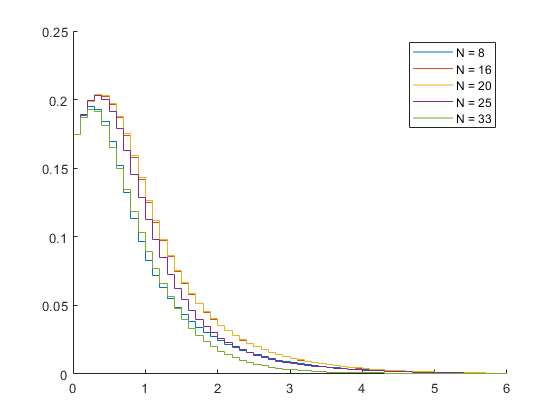

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_8.mat')
x_Q_100000_R_1_N_8 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_9.mat')
x_Q_100000_R_1_N_9 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_12.mat')
x_Q_100000_R_1_N_12 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_16.mat')
x_Q_100000_R_1_N_16 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_20.mat')
x_Q_100000_R_1_N_20 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_25.mat')
x_Q_100000_R_1_N_25 = x;

load('MPC_reg_states_different_N\States_v_2_Q_100000_R_1_N_33.mat')
x_Q_100000_R_1_N_33 = x;

figure(2)
hold on
stairs(t,x_Q_100000_R_1_N_8(1,:))
stairs(t,x_Q_100000_R_1_N_16(1,:))
stairs(t,x_Q_100000_R_1_N_20(1,:))
stairs(t,x_Q_100000_R_1_N_25(1,:))
stairs(t,x_Q_100000_R_1_N_33(1,:))
legend('N = 8','N = 16','N = 20','N = 25','N = 33')
hold off